# CS283 Assignment 5

Enmao Diao, 2017/10/13

*Note: Matlab requires that all local functions in a live script appear at the end of the script. So, your code defining functions must appear at the very bottom of this file, after all other code that makes references to those functions. Also, each function definition must terminate with "end". More information is in the *[Matlab documentation](https://www.mathworks.com/help/matlab/matlab_prog/local-functions-in-scripts.html)*.*

# Question 1, 10 Points

(a)

We use tylar series expansion for$x+h,x-h,x+2h,x-2h$


$$f(x+h) = f(x) + hf\prime(x)+\frac{h^2}{2}f^{(2)}(x)+\frac{h^3}{3!}f^{(3)}(x)+\frac{h^4}{4!}f^{(4)}(x)+O(h^5)
$$



$$f(x-h) = f(x) - hf\prime(x)+\frac{h^2}{2}f^{(2)}(x)-\frac{h^3}{3!}f^{(3)}(x)+\frac{h^4}{4!}f^{(4)}(x)+O(h^5)
$$



$$f(x+2h) = f(x) + 2hf\prime(x)+2h^2f^{(2)}(x)+\frac{(2h)^3}{3!}f^{(3)}(x)+\frac{(2h)^4}{4!}f^{(4)}(x)+O(h^5)
$$



$$f(x-2h) = f(x) - 2hf\prime(x)+2h^2f^{(2)}(x)+\frac{(2h)^3}{3!}f^{(3)}(x)-\frac{(2h)^4}{4!}f^{(4)}(x)+O(h^5)
$$



$$f(x+h)-f(x-h) = 2hf\prime(x)+\frac{2h^3}{3!}f^{(3)}(x)+O(h^5)$$



$$f(x+2h)-f(x-2h) = 4hf\prime(x)+\frac{2^4h^3}{3!}f^{(3)}(x)+O(h^5)$$


Thus,


$$8(f(x+h)-f(x-h)) = 16hf\prime(x)+\frac{2^4h^3}{3!}f^{(3)}(x)+O(h^5)$$



$$f\prime(x) = \frac{-f(x+2h)+8f(x+h)-8f(x-h)+f(x+2h)}{12h}+O(h^4)$$


(b) from the equation above, we can conclude that the corresponding convolution kernel is $(-1/12,8/12,0,-8/12,1/12)$

# Question 2, 20 Points

(a) We simply change a little from the helper function. See deriv.m

(b) We check whether there exist two zero cross for any pixel $(i,j)$. We then compute the sub-pixel zero-crossing coordinates and choose their mid point as our final edgel.

(c) For each edgel, we sample with interp2 from $I_x$ and $I_y$ which are computed from convolution between gaussin derivative filter and images. From our experiment, we find $\sigma = 0.6$ provides reasonable result.

im = imread('./data/calib_right.bmp');
sigma = 0.6

sigma = 0.6000

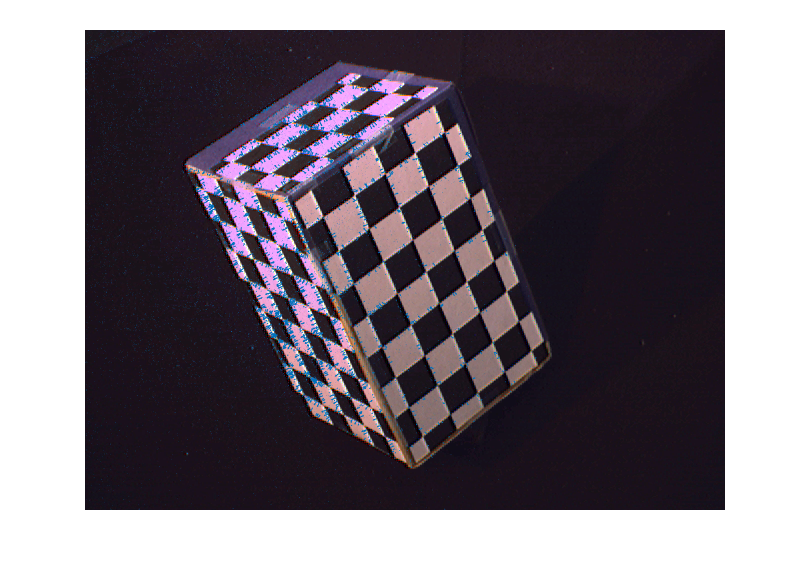

[X,G] = edgels(im,sigma);
figure
imshow(im)
hold on
quiver(X(:,1),X(:,2),G(:,1),G(:,2))

# Question 3, 20 Points

(a) We use expression suggested from the textbook. Since we choose a rather small $\alpha$, we mainly focus on maximizing $ \lambda_0\lambda_1$ with some moderate penalization. We want to select points with surfaces that have principal curvatures with larger $ \lambda_0\lambda_1$ as shown in the assignment and slides. We try to avoid the case where $ \lambda_0$ and $\lambda_1$ have different sign. 


$$C(x,y) = \lambda_0\lambda_1-\alpha( \lambda_0+\lambda_1)^2, \alpha =0.06$$



$$=\det(\mathcal H)-trace(\mathcal H)^2$$



$$=K(x,y)-4H(x,y)^2$$


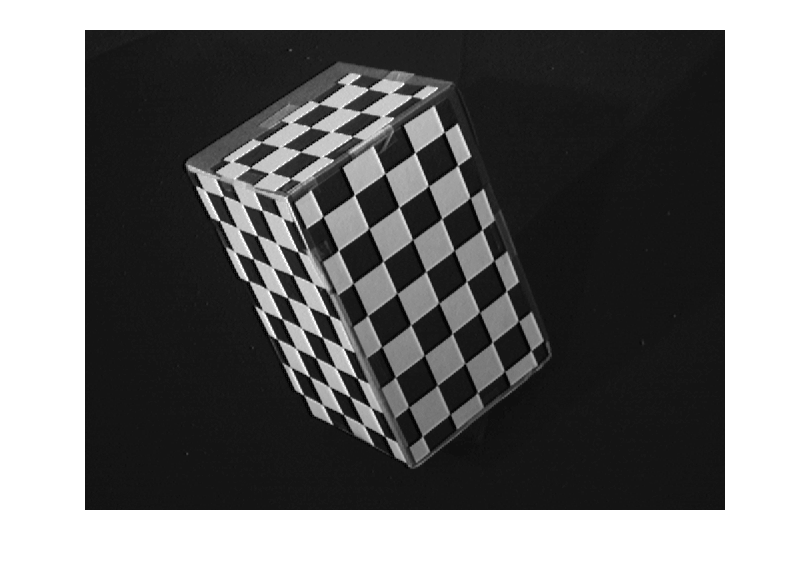

im_org = imread('./data/calib_right.bmp');
if size(im_org,3)>1
	im=im2double(rgb2gray(im_org));
else
	im=im2double(im_org);
end
figure;
imshow(im)

(b) We compute the Hessian matrix $\mathcal H$. We compute second derivative of Gaussian derivative filter $G_\sigma(x,y)$ and convolve with them the image. We end up with $I_{xx},I_{yy},I_{xy},I_{yx}$, $I_{xy}=I_{yx}$, and all have size of the image.

Then $K(x,y) = \det(\mathcal H) = I_{xx}\bigodot I_{yy} - I_{xy}\bigodot I_{yx}$, $\bigodot$ denote element-wise product, $H(x,y) = \frac{1}{2}trace(\mathcal H) = \frac{1}{2}(I_{xx}+I_{yy})$

Follow the equation in (a) we obtain $C(x,y)$

sigma = 2

sigma = 2

threshold = 1

threshold = 1

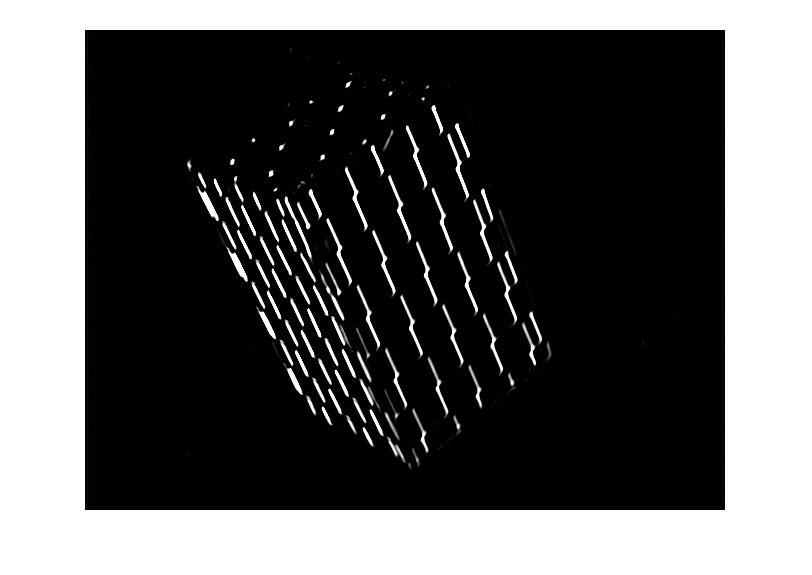

C = cornerness(im,sigma);
figure
imshow(C)

(c) We use image dilation as a local-maximum operator with 3x3 square morphological structuring element. See nonmax_suppression.m. Through experiment, condition on $\sigma =2$, we use $threshold = 1$.

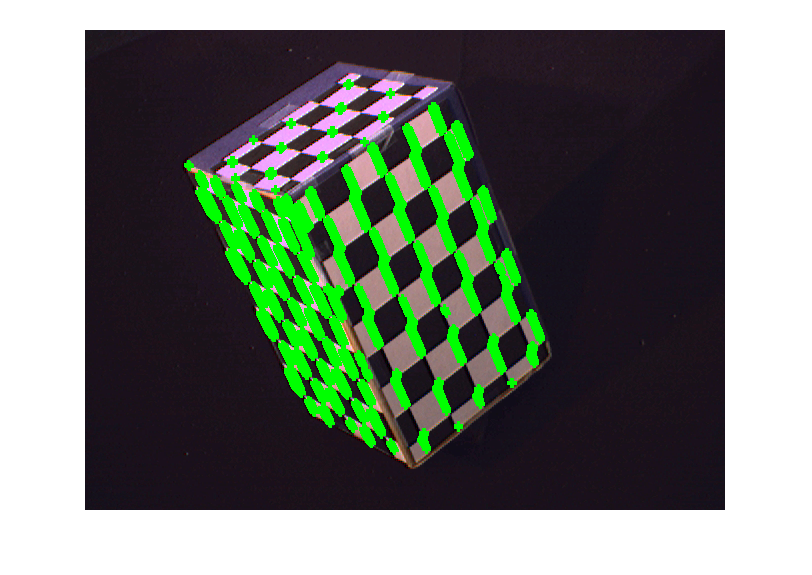

Co = nonmax_suppression(C);
[I,J] = ind2sub(size(im),find(Co>threshold));
overlay_C = insertMarker(im_org,[J,I]);
figure
imshow(overlay_C)

# Question 4, 10 Points


$$(G_{s_1}*G_{s_2})(x) = \int_{-\infty}^{+\infty}G_{s_1}(x)G_{s_2}(x-y) dy$$



$$=\int_{-\infty}^{+\infty}\frac{1}{\sqrt{2\pi s_1}}\exp(-\frac{y^2}{2s_1})\frac{1}{\sqrt{2\pi s_2}}exp(-\frac{(x-y)^2}{2s_2}) dy$$



$$=\frac{1}{\sqrt{2\pi s_1}}\frac{1}{\sqrt{2\pi s_2}}\int_{-\infty}^{+\infty}\exp(\frac{-s_2y^2-s_1x^2+2s_1xy-s_1y^2}{2s_1s_2}) dy$$



$$=\frac{1}{\sqrt{2\pi s_1}}\frac{1}{\sqrt{2\pi s_2}}\int_{-\infty}^{+\infty}\exp(-\frac{(s_1+s_2)y^2-2s_1xy+s_1x^2}{2s_1s_2}) dy$$



$$=\frac{1}{\sqrt{2\pi s_1}}\frac{1}{\sqrt{2\pi s_2}}\int_{-\infty}^{+\infty}\exp(-\frac{y^2-2\frac{s_1}{s_1+s_2}xy+\frac{s_1}{s_1+s_2}x^2}{2\frac{s_1s_2}{s_1+s_2}}) dy$$


by completing the square


$$=\frac{1}{\sqrt{2\pi s_1}}\frac{1}{\sqrt{2\pi s_2}}\int_{-\infty}^{+\infty}\exp(-\frac{(y-\frac{s_1}{s_1+s_2}x)^2-(\frac{s_1}{s_1+s_2}x)^2+\frac{s_1}{s_1+s_2}x^2}{2\frac{s_1s_2}{s_1+s_2}}) dy$$



$$=\frac{1}{\sqrt{2\pi (s_1+s_2)}}\exp(-\frac{\frac{s_1}{s_1+s_2}x^2-(\frac{s_1}{s_1+s_2}x)^2}{2\frac{s_1s_2}{s_1+s_2}})\frac{1}{\sqrt{2\pi \frac{s_1s_2}{s_1+s_2}}}\int_{-\infty}^{+\infty}\exp(-\frac{(y-\frac{s_1}{s_1+s_2}x)^2}{2\frac{s_1s_2}{s_1+s_2}}) dy$$


The right integration can be viewed as a integration of normal distribution with mean $\frac{s_1}{s_1+s_2}x$ and variance $\frac{s_1s_2}{s_1+s_2}$ from $-\infty$ to $+\infty$.  It integrates to 1 due to the definition of probability distribution function.


$$=\frac{1}{\sqrt{2\pi (s_1+s_2)}}\exp(-\frac{s_1(s_1+s_2)x^2-s_1^2x^2}{2s_1s_2(s_1+s_2)})$$



$$=\frac{1}{\sqrt{2\pi (s_1+s_2)}}\exp(-\frac{s_1s_2x^2}{2s_1s_2(s_1+s_2)})$$



$$=\frac{1}{\sqrt{2\pi (s_1+s_2)}}\exp(-\frac{x^2}{2(s_1+s_2)})$$



$$=G_{s_1+s_2}(x)$$


# Local Functions

function [X,G]=edgels(im,sigma)
%EDGELS   Edge detector based on Laplacian of Gaussian
%  [X,G]=EDGELS(IM,SIGMA) computes edges in image IM at the scale given by
%  the scalar value SIGMA. SIGMA is the standard deviation (in pixels) of
%  the Gaussian filters used to computed first and second derivatives in
%  the image.
%
%  The output X is an Nx2 array, where each row is the (x,y) position of an
%  edge point (or 'edgel'). Edgels are localized to sub-pixel accuracy, so
%  these coordinates are not generally integers. The output G is another
%  Nx2 array that stores the gradient vector at each edge point. 
%
%  The norm of each row of Dx provides the gradient magnitudes, for example, and
%  edgels with small gradient magnitudes can be removed as a post-process,
%  by performing additional operations on the [X,G] returned by this function.
%
%  Reference:
%  ----------
%  Closely related to the algorithm described in Chapter Four of R.
%  Szeliski, "Computer Vision: Algorithms and Applications", available in
%  draft form at http://research.microsoft.com/en-us/um/people/szeliski/Book/

% convert image to double grayscale (so intensity values are in [0,1])
if size(im,3)>1
	im=im2double(rgb2gray(im));
else
	im=im2double(im);
end

% LoG response
Ilog=conv2(im,lapgauss(sigma),'same');

% locate the four-pixel squares having exactly two
%   zero-crossings along their four pair-wise connections
%<your code here>
S = Ilog>0;
[n,m]=size(im);
Z = zeros(n,m);
for i=1:n-1
    for j=1:m-1
        Z(i,j) = (double(S(i,j)~=S(i,j+1))+double(S(i,j)~=S(i+1,j))) == 2;
    end
end
% sub-pixel localization of these surviving zero-crossings. Use Szeliski 
%   equation 4.25. Note that the equation has a type-o; the formula should use 
%   directly the values of the LoG response Ilog, instead of their signs 
%   S(Ilog).
%<your code here>
[I,J]=ind2sub([n,m],find(Z==1));
X = zeros(length(I),2);
for i=1:length(I)
    cx1 = I(i).*Ilog(I(i)+1,J(i))-(I(i)+1).*Ilog(I(i),J(i))/(Ilog(I(i)+1,J(i))-Ilog(I(i),J(i)));
    cy1 = J(i);
    cx2 = I(i);
    cy2 = J(i).*Ilog(I(i),J(i)+1)-(J(i)+1).*Ilog(I(i),J(i))/(Ilog(I(i),J(i)+1)-Ilog(I(i),J(i)));
    X(i,1) = (cx1+cx2)/2;
    X(i,2) = (cy1+cy2)/2;
end
% sample the image gradient at these localized points. (The 
%   localized points are assumed to be in an Nx2 array X 
%   with rows of the form (x,y).)
%<your code here>
[Dx,Dy] = deriv(sigma);
Jgradx=conv2(im,Dx,'same');
Jgrady=conv2(im,Dy,'same');
G = zeros(length(I),2);
G(:,1)=interp2(Jgradx,X(:,1),X(:,2));
G(:,2)=interp2(Jgrady,X(:,1),X(:,2));
%%% SUB-ROUTINESD
%%%
end

function [Dx,Dy]=deriv(sigma)
% Create derivative-of-Gaussian kernels for horizontal and vertical derivatives.
% Input SIGMA is the standard deviation of the Gaussian. Use equation 4.21 
% in the Szelsiki book. Note that the equation has a type-o; the multiplicative 
% factor 1/sigma^3 should instead be 1/sigma^4; this does not affect the results
% though.

%<your code here>
w=2*floor(ceil(7*sigma)/2)+1;
[xx,yy]=meshgrid(-(w-1)/2:(w-1)/2,-(w-1)/2:(w-1)/2);

Dx=(1/(sigma^4)).*(-xx).*exp(-(xx.^2+yy.^2)/(2*sigma^2));
Dy=(1/(sigma^4)).*(-yy).*exp(-(xx.^2+yy.^2)/(2*sigma^2));
end

function DD=lapgauss(sigma)
% Create Laplacian-of-Gaussian kernel with standard deviation SIGMA.
% Use equation 4.23 in the Szelsiki book.

% use an odd-size square window with length greater than 5 times sigma
w=2*floor(ceil(7*sigma)/2)+1;
[xx,yy]=meshgrid(-(w-1)/2:(w-1)/2,-(w-1)/2:(w-1)/2);

% Equation 4.23 from Szeliski's book. (Actually, he has a small type-o; 
%   the equation here is correct)
DD=(1/(sigma^4)).*(1-(xx.^2+yy.^2)/(2*sigma^2)).*exp(-(xx.^2+yy.^2)/(2*sigma^2));

return;
end


function C=cornerness(I,sigma)
w=2*floor(ceil(7*sigma)/2)+1;
[xx,yy]=meshgrid(-(w-1)/2:(w-1)/2,-(w-1)/2:(w-1)/2);
Dxx=(1/(sigma^4)).*(xx.^2-sigma^2).*exp(-(xx.^2+yy.^2)/(2*sigma^2));
Dyy=(1/(sigma^4)).*(yy.^2-sigma^2).*exp(-(xx.^2+yy.^2)/(2*sigma^2));
Dxy=(1/(sigma^4)).*(xx.*yy-sigma^2).*exp(-(xx.^2+yy.^2)/(2*sigma^2));
Ixx=conv2(I,Dxx,'same');
Iyy=conv2(I,Dyy,'same');
Ixy=conv2(I,Dxy,'same');
K = Ixx.*Ixy-Iyy.^2;
H = 1/2*(Ixx+Ixy);
alpha = 0.06;
C = K-alpha*4*H.^2;
end

function Co=nonmax_suppression(C)
SE = strel('square',3);
Co = imdilate(C,SE);
end